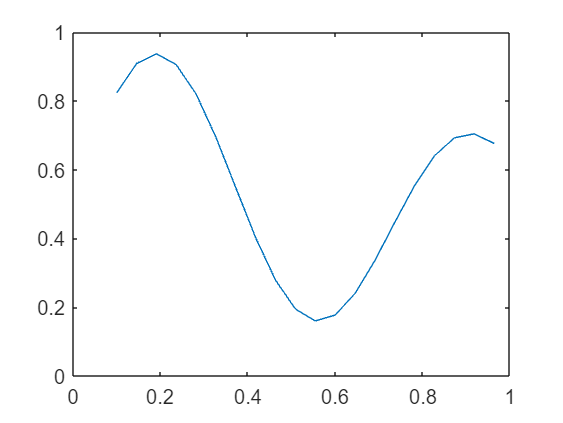

clear
x = 0.1: 1/22: 1;
n = 0.3;
d = (1 + 0.6 * sin (2 * pi * x / 0.7) + 0.3 * sin (2 * pi * x)) / 2;
plot(x, d)

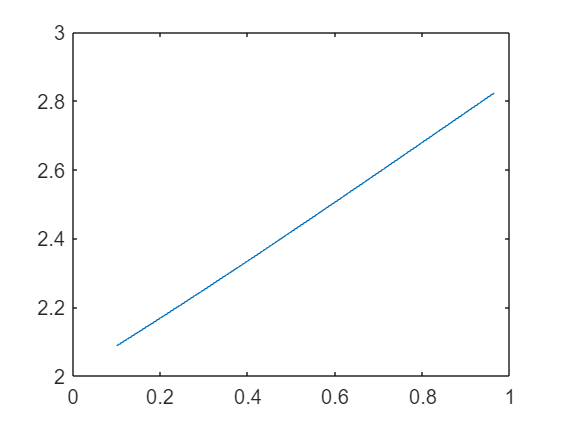

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the
number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for
elementwise multiplication.

Related documentation


activ_func = @(x, w, b, ind) (1./(1+exp(((-1)*x(ind).*w(1, :)) + b)));
act_deriv = @(x, w, b, ind) (activ_func(x, w, b, ind).*(1 - activ_func(x, w, b, ind)));

w = rand(2, 8);
b = rand(1, 8);
b21 = rand(1);

y_fin = zeros((size(d)));
y = zeros(1, 8, 20);
while true
    for index = 1:20
        y(:, :, index) = activ_func(x, w, b, index);
    end
    
    for index = 1:20
        y_fin(index) = sum(y(:, :, index).*w(2, :));
    end
    y_fin = y_fin + b21;
    plot(x, y_fin)
    e = d - y_fin;
    if abs(sum(e)) < 0.1
        break
    end
    for index = 1:20
%         w(2,:) = w(2,:)+n.*e(index).*y(:, :, index);
%         b21 = b21 + n*e(index);
%         w(1,:) = w(1,:) + n.*act_deriv(x, w, b, index).*x(index);
%         b = b + n*act_deriv(x, w, b, index);
        loss(index) = 2 .* e(index) * act_deriv(x, w, b, index) .* x(index);

    end
end